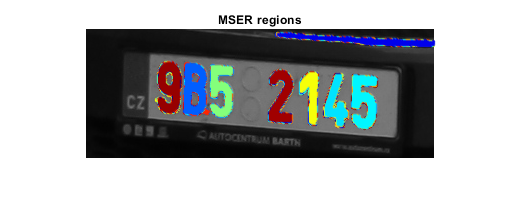

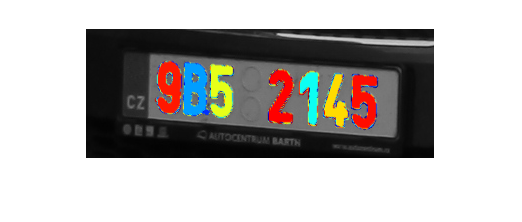

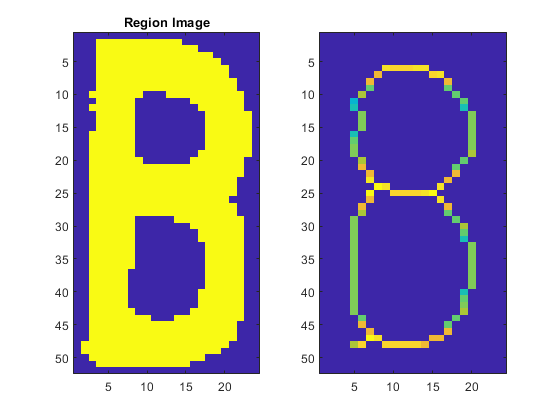

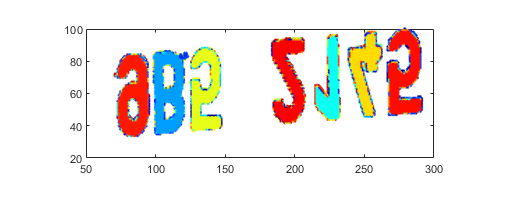

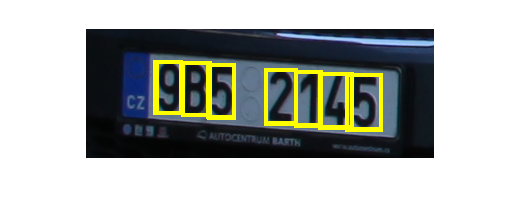

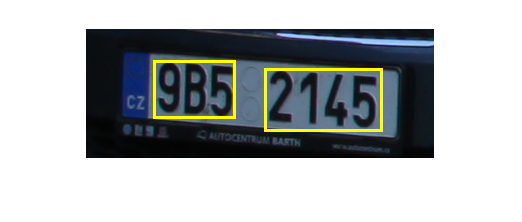

str =     '985
     
     2145/
     
     '


str = '9852145/'

str = '9852145'

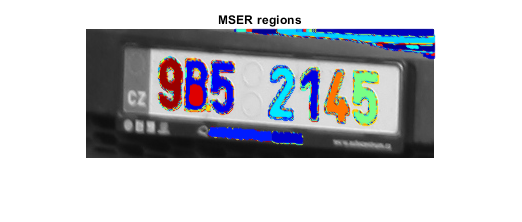

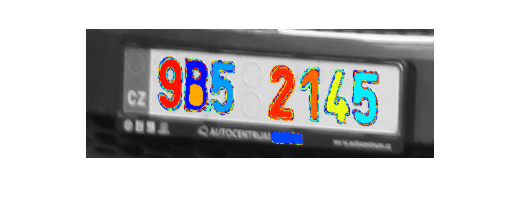

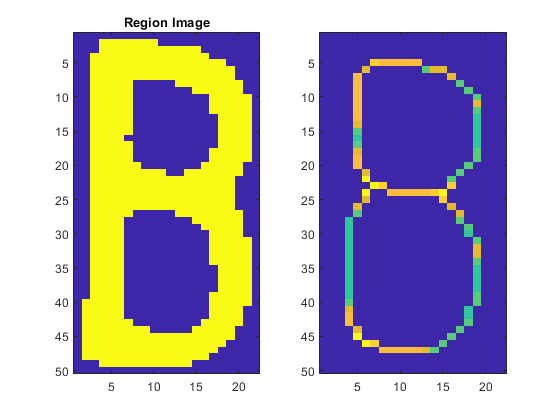

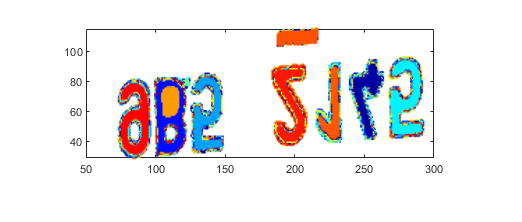

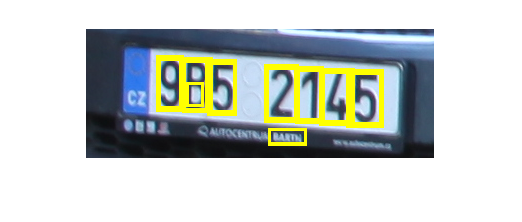

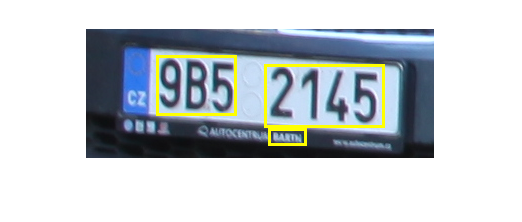

str =     '9B5
     
     2145
     
      
     
     '


str = '9B52145'

str = '9B52145'

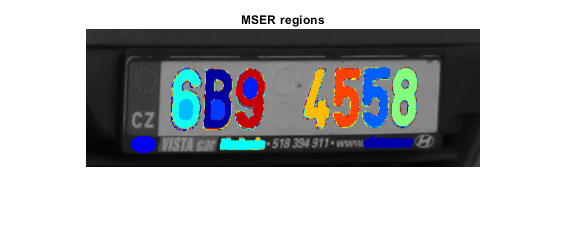

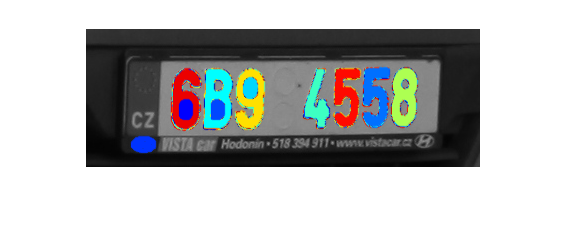

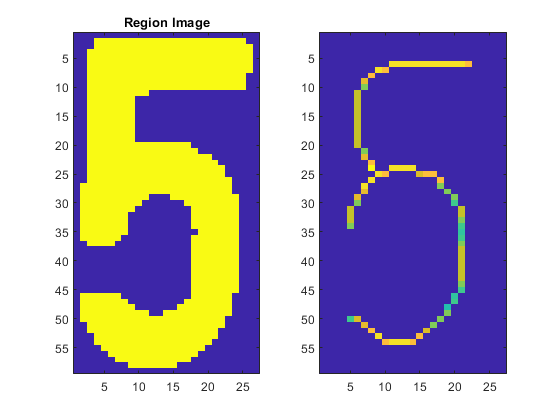

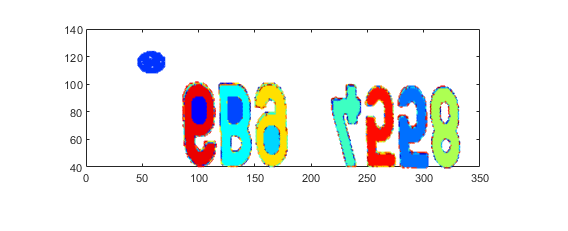

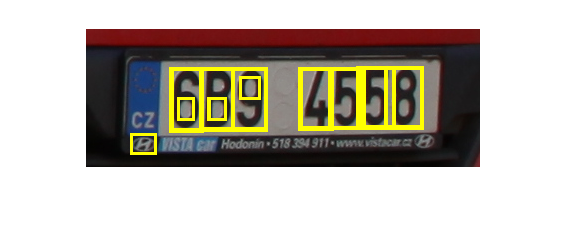

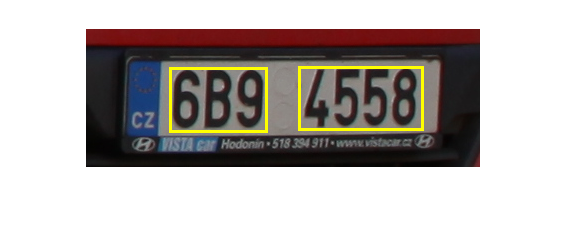

str =     '4558
     
     6B9
     
     '


str = '45586B9'

str = '45586B9'

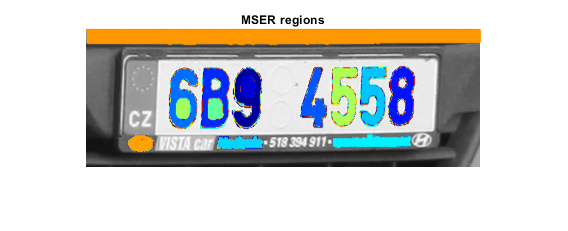

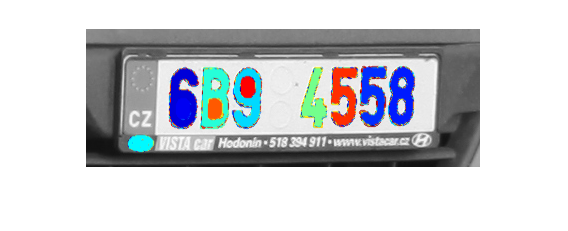

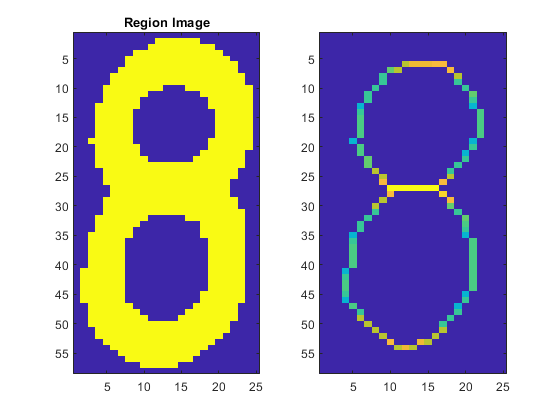

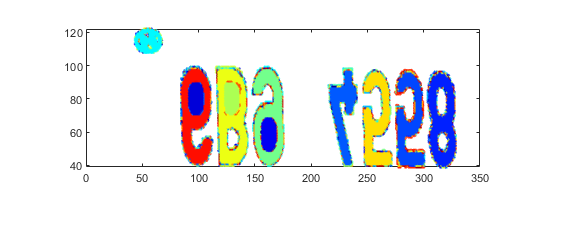

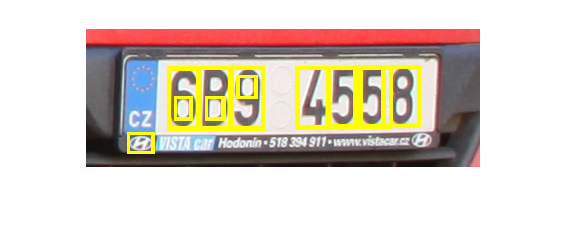

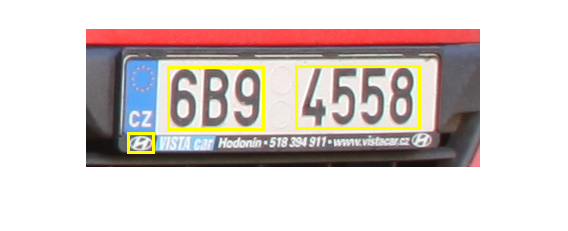

str =     '4558
     
     6B9
     
     '


str = '45586B9'

str = '45586B9'

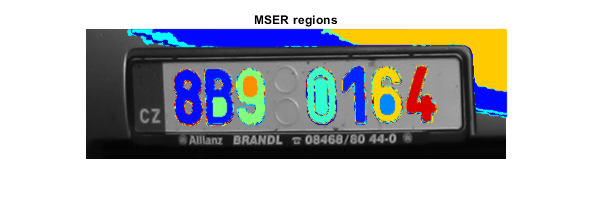

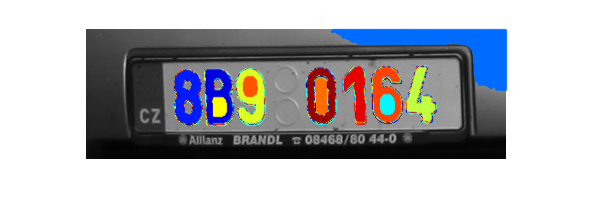

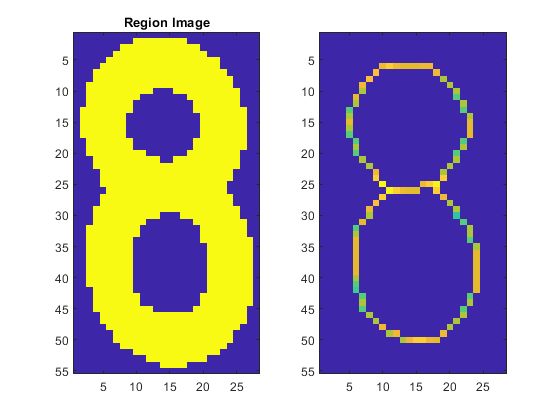

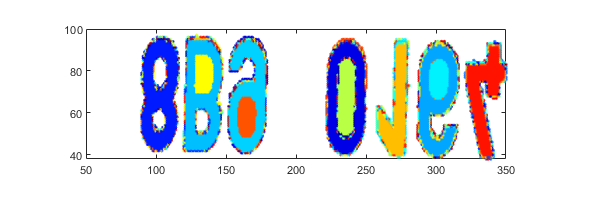

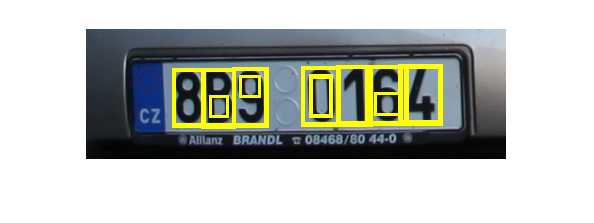

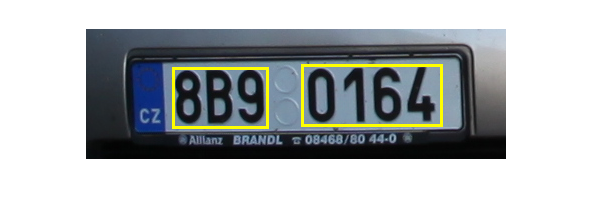

str =     '8B9
     
     0164
     
     '


str = '8B90164'

str = '8B90164'

clear

datatable = readtable('trainVal.csv', 'ReadVariableNames', true); 
%or true if there is a header
numRows = height(datatable);
imagePaths = datatable(:,2);
text = [];
imagePaths= string(datatable.image_path);
imagePaths= erase(imagePaths,'./');
imagePaths= strrep(imagePaths,'/','\');



for i=1:5
    
colorImage = imread(char(imagePaths(i)));
I = rgb2gray(colorImage);

% Detect MSER regions.
[mserRegions, mserConnComp] = detectMSERFeatures(I, ... 
    'RegionAreaRange',[200 8000],'ThresholdDelta',4);

figure
imshow(I)
hold on
plot(mserRegions, 'showPixelList', true,'showEllipses',false)
title('MSER regions')
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Use regionprops to measure MSER properties
mserStats = regionprops(mserConnComp, 'BoundingBox', 'Eccentricity', ...
    'Solidity', 'Extent', 'Euler', 'Image');

% Compute the aspect ratio using bounding box data.
bbox = vertcat(mserStats.BoundingBox);
w = bbox(:,3);
h = bbox(:,4);
aspectRatio = w./h;

% Threshold the data to determine which regions to remove. These thresholds
% may need to be tuned for other images.
filterIdx = aspectRatio' > 3; 
filterIdx = filterIdx | [mserStats.Eccentricity] > .995 ;
filterIdx = filterIdx | [mserStats.Solidity] < .3;
filterIdx = filterIdx | [mserStats.Extent] < 0.2 | [mserStats.Extent] > 0.9;
filterIdx = filterIdx | [mserStats.EulerNumber] < -4;

% Remove regions
mserStats(filterIdx) = [];
mserRegions(filterIdx) = [];

% Show remaining regions
figure
imshow(I)
hold on
plot(mserRegions, 'showPixelList', true,'showEllipses',false)
%title('After Removing Non-Text Regions Based On Geometric Properties');
% hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get a binary image of the a region, and pad it to avoid boundary effects
% during the stroke width computation.
regionImage = mserStats(6).Image;
regionImage = padarray(regionImage, [1 1]);

% Compute the stroke width image.
distanceImage = bwdist(~regionImage); 
skeletonImage = bwmorph(regionImage, 'thin', inf);

strokeWidthImage = distanceImage;
strokeWidthImage(~skeletonImage) = 0;

% Show the region image alongside the stroke width image. 
figure
subplot(1,2,1)
imagesc(regionImage)
title('Region Image')

subplot(1,2,2)
imagesc(strokeWidthImage)
%title('Stroke Width Image');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Compute the stroke width variation metric 
strokeWidthValues = distanceImage(skeletonImage);   
strokeWidthMetric = std(strokeWidthValues)/mean(strokeWidthValues);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Threshold the stroke width variation metric
strokeWidthThreshold = 0.4;
strokeWidthFilterIdx = strokeWidthMetric > strokeWidthThreshold;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Process the remaining regions
for j = 1:numel(mserStats)
    
    regionImage = mserStats(j).Image;
    regionImage = padarray(regionImage, [1 1], 0);
    
    distanceImage = bwdist(~regionImage);
    skeletonImage = bwmorph(regionImage, 'thin', inf);
    
    strokeWidthValues = distanceImage(skeletonImage);
    
    strokeWidthMetric = std(strokeWidthValues)/mean(strokeWidthValues);
    
    strokeWidthFilterIdx(j) = strokeWidthMetric > strokeWidthThreshold;
    
end

% Remove regions based on the stroke width variation
mserRegions(strokeWidthFilterIdx) = [];
mserStats(strokeWidthFilterIdx) = [];

% Show remaining regions
figure
imshow(I)
%hold on
plot(mserRegions, 'showPixelList', true,'showEllipses',false)
%title('After Removing Non-Text Regions Based On Stroke Width Variation');
%hold off
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Get bounding boxes for all the regions
bboxes = vertcat(mserStats.BoundingBox);

% Convert from the [x y width height] bounding box format to the [xmin ymin
% xmax ymax] format for convenience.
xmin = bboxes(:,1);
ymin = bboxes(:,2);
xmax = xmin + bboxes(:,3) - 1;
ymax = ymin + bboxes(:,4) - 1;

% Expand the bounding boxes by a small amount.
expansionAmount = 0.02;
xmin = (1-expansionAmount) * xmin;
ymin = (1-expansionAmount) * ymin;
xmax = (1+expansionAmount) * xmax;
ymax = (1+expansionAmount) * ymax;

% Clip the bounding boxes to be within the image bounds
xmin = max(xmin, 1);
ymin = max(ymin, 1);
xmax = min(xmax, size(I,2));
ymax = min(ymax, size(I,1));

% Show the expanded bounding boxes
expandedBBoxes = [xmin ymin xmax-xmin+1 ymax-ymin+1];
IExpandedBBoxes = insertShape(colorImage,'Rectangle',expandedBBoxes,'LineWidth',3);

figure
imshow(IExpandedBBoxes)
%title('Expanded Bounding Boxes Text');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Compute the overlap ratio
overlapRatio = bboxOverlapRatio(expandedBBoxes, expandedBBoxes);

% Set the overlap ratio between a bounding box and itself to zero to
% simplify the graph representation.
n = size(overlapRatio,1); 
overlapRatio(1:n+1:n^2) = 0;

% Create the graph
g = graph(overlapRatio);

% Find the connected text regions within the graph
componentIndices = conncomp(g);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Merge the boxes based on the minimum and maximum dimensions.
xmin = accumarray(componentIndices', xmin, [], @min);
ymin = accumarray(componentIndices', ymin, [], @min);
xmax = accumarray(componentIndices', xmax, [], @max);
ymax = accumarray(componentIndices', ymax, [], @max);

% Compose the merged bounding boxes using the [x y width height] format.
textBBoxes = [xmin ymin xmax-xmin+1 ymax-ymin+1];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Remove bounding boxes that only contain one text region
numRegionsInGroup = histcounts(componentIndices);
textBBoxes(numRegionsInGroup == 1, :) = [];

% Show the final text detection result.
ITextRegion = insertShape(colorImage, 'Rectangle', textBBoxes,'LineWidth',3);

figure
imshow(ITextRegion)
%title('Detected Text');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ocrtxt = ocr(I, textBBoxes);
str = [ocrtxt.Text]
str = str(find(~isspace(str)))
str = erase(str,'/')
text = [text str];

end


accuracy = text ~= string(datatable.lp);
accuracy = sum(accuracy(:) == 1)/nume(text)

ans = 130.4000